# Calibrate Propeller+Motor Thrust and Torque

In this script we'll import some experimental data consisting of measured propeller speed and the Thrust and Torque produced at these speeds.  We'll then construct a prediction equation that allows us to predict the thrust or torque given the motor speed.  For both Thrust and Torque we'll fit a "pure" quadratic equation against motor speed, ie: 

- 
$$THRUST= k_F\times\omega^2$$


- 
$$TORQUE= k_M\times\omega^2$$


where the motor speed is $\omega$ (rad/sec).

`Bradley Horton : 01-Jun-2016, bradley.horton@mathworks.com.au`

## Read in MEASUREMENT data from XLS file

Our first step is to import the measurement data from the Excel file, into MATLAB.

PROP_MEAS_DATA = readtable('bh_MEASURED_DATA_PROP_AND_MOTOR.xlsx', ...
                           'Sheet', 'PROP_AND_MOTOR')
                       

Note that the data is imported into MATLAB as a ***table*** data type.  Have you seen these before? - they're kind of like a hybrid between a "standard" matrix and a user defined "struct". Very cool !

## Plot the measurement data

Before we do any curve fitting, let's just plot our measurement data:

W      = PROP_MEAS_DATA.w_rad_per_sec; 
THRUST = PROP_MEAS_DATA.THRUST_N;
TORQUE = PROP_MEAS_DATA.TWIST_N_per_m;

figure;
subplot(1,2,1);
   plot(W,THRUST,'o-r');
        xlabel('W (rad/sec)'); ylabel('THRUST (N)');  axis('tight'); grid('on');
        legend('MEAS Thrust','Location','northwest'); title(gca,'Measurement data');
subplot(1,2,2);
   plot(W,TORQUE,'o-b');
        xlabel('W (rad/sec)'); ylabel('TORQUE (N.m)'); axis('tight'); grid('on');
        legend('MEAS Torque','Location','northwest');  title(gca,'Measurement data');

## THRUST - Regression fit

Let's perform the quadratic regression fit for our thrust data.  The model that we are trying to produce, has the following form:


$$THUST_{predicted} = k_F \times \omega^2$$


We'll determine the thrust co-efficient "*k*" using a least squares fit.  Recall from our Numerical methods class, how we solve a "general" linear regression problem. Given a measurement vector $y \in R^{\thinspace n\times1}$ and a prediction equation of the form $y_{pred}=A \thinspace . \thinspace x$, then find the design variable $x \in R^{\thinspace m \times 1}$ that minimizes the sum of squared errors $e$:


$$\matrix{
e = &  {(y-y_{pred})}^T . (y-y_{pred}) \cr 
e = &  {(y-A.x)}^T . (y-A.x) \cr 
e = &  (y^T -x^T.A^T).(y-A.x) \cr 
e = & y^T.y - y^T.A.x - x^T.A^T.y + x^TA^T.A.x \cr 
}
$$


Setting the derivative w.r.t *x* to zero, and using the "[denominator layout convention](https://en.wikipedia.org/wiki/Matrix_calculus)", we get:


$$\frac{de}{dx} = 0 = -A^T.y -A^T.y + 2.A^T.A.x$$



$$A^T.A.x = A^T.y $$



$$x = (A^T.A)^{-1}.A^T.y$$


This same problem in MATLAB can be solved using psudo-inverse function `pinv().` In MATLAB these types of matrix equations are best solved using the "famous" BACKSLASH operator:


$$k_F =x=A\backslash b$$


A   = W.^2;
b   = THRUST;
kF  = A\b

## TORQUE - Regression fit

For our TORQUE prediction equation, we'll again use a "pure" quadratic equation, ie:


$$TORQUE_{predicted} = k_M \times \omega^2$$


A   = W.^2;
b   = TORQUE;
kM  = A\b

# 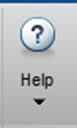 Take a moment !

If you're interested in the broad topic of curve fitting, don't forget how useful MATLAB's HELP browser can be. As an experiment, here's a simple text search using the HELP Browser:

doc curve fitting

## COMPARE - Measured versus predicted

w_syn   = linspace(min(W), max(W), 100)';
TH_pred = w_syn.^2 * kF;
TQ_pred = w_syn.^2 * kM;

figure
subplot(1,2,1);
    plot(W,THRUST,'o-r');     hold('on');
    plot(w_syn,TH_pred,'.k');
        xlabel('W (rad/sec)'); ylabel('THRUST (N)');
        axis('tight'); grid('on');
        legend({'MEAS Thrust', 'PRED Thrust'},'Location','northwest');
subplot(1,2,2);
    plot(W,TORQUE,'o-b');   hold('on');
    plot(w_syn,TQ_pred,'.k');
        xlabel('W (rad/sec)'); ylabel('TORQUE (N.m)');
        axis('tight'); grid('on');
        legend({'MEAS Torque','PRED Torque'},'Location','northwest');
        

# Why not use the Curve Fitting toolbox app ?

It was nice solving this curve fitting problem from first principles, but an alternate approach would be to use the curve fitting app that ships with teh Curve Fitting Toolbox.  Let's open a session that I've saved earlier:

cftool('bh_cvfit_app_session.sfit')

Note how our calculated THRUST and TORQUE constants are the same as those calculated using the "manual" least squares approach:

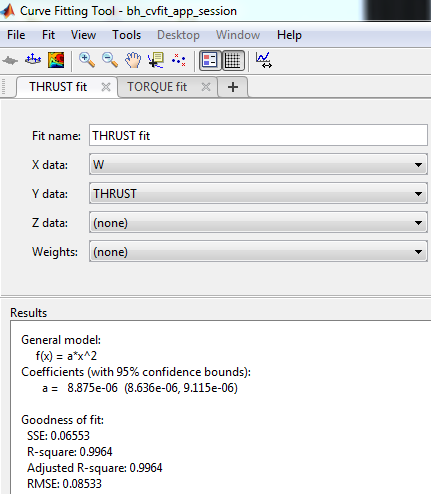   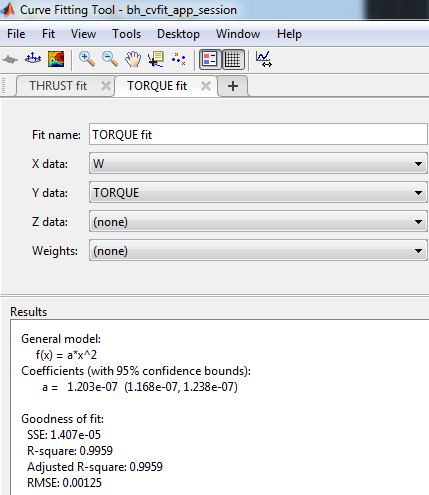

# Recall how these pieces come together in our Quadcopter model: